% Sélection du fichier audio
[file, path] = uigetfile(...
    {'*.wav;*.flac;*.mp3;*.mp4', 'Fichiers audio (*.wav;*.flac;*.mp3;*.mp4)'},...
    'Selectionnez un fichier audio');

if file == 0
    return;
end

% Informations générales sur la musique
audioInfo = audioinfo(fullfile(path, file))

audioInfo = struct with fields:
             Filename: 'C:\Users\Camille\Desktop\dragon-quest-xi-symphonic-saints-wreath-vi.mp3'
    CompressionMethod: 'MP3'
          NumChannels: 2
           SampleRate: 48000
         TotalSamples: 11023488
             Duration: 229.6560
                Title: 'Dragon Quest XI [Symphonic] - Saint's Wreath (VI)'
              Comment: []
               Artist: 'dochalkos'
              BitRate: 250.2960


fe = audioInfo.SampleRate % fréquence d'échantillonnage

fe = 48000

Dobs = 0.5; %Durée d'observation (s)
te = 0:1/fe:Dobs-1/fe; % période d'échantillonnage
% Vecteur temps
[audio,~]=audioread(fullfile(path, file));

audio =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


%Tanspose la matrice pour avoir le temps le long des colonnes
audio = audio.';

% Evolution de l'audio en temporelle et fréquentielle
%Axe temporel
t = (0:size(audio,2)-1)/fe;
%Axe fréquentiel
f=linspace(0,fe,size(audio,2));
%Magnitude TF(audio)
TF_audio =abs(fft(audio,[], 2));

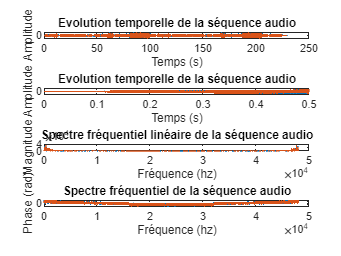


% Représentation

figure;
subplot(4,1,1);
plot(t, audio.');
xlabel('Temps (s)');
ylabel('Amplitude');
title('Evolution temporelle de la séquence audio');

subplot(4,1,2);
plot(t, audio.');
xlabel('Temps (s)');
ylabel('Amplitude');
title('Evolution temporelle de la séquence audio');
xlim([0, 0.5]);

subplot(4,1,3);
plot(f, TF_audio.');
xlabel('Fréquence (hz)');
ylabel('Magnitude');
title('Spectre fréquentiel linéaire de la séquence audio');

subplot(4,1,4);
plot(f, 20*log10(TF_audio).');
xlabel('Fréquence (hz)');
ylabel('Phase (rad)');
title('Spectre fréquentiel de la séquence audio');

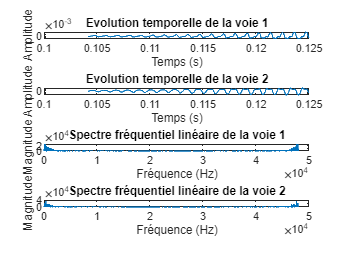


nech0 = 5000;
nbech = 1000;
Nobs = nech0+(1:nbech);

% Représentation
figure;

% Evolution temporelle des voies audioSource sur l'intervalle Nobs
subplot(4,1,1);
plot(t(Nobs), audio(1,Nobs));
xlabel('Temps (s)');
ylabel('Amplitude');
title('Evolution temporelle de la voie 1');

subplot(4,1,2);
plot(t(Nobs), audio(2,Nobs));
xlabel('Temps (s)');
ylabel('Amplitude');
title('Evolution temporelle de la voie 2');

% Spectre fréquentiel linéaire de la séquence audio
subplot(4,1,3);
plot(f, TF_audio(1,:));
xlabel('Fréquence (Hz)');
ylabel('Magnitude');
title('Spectre fréquentiel linéaire de la voie 1');

subplot(4,1,4);
plot(f, TF_audio(2,:));
xlabel('Fréquence (Hz)');
ylabel('Magnitude');
title('Spectre fréquentiel linéaire de la voie 2');


% Convertir le spectre en décibels
TF_audio_dB = 20*log10(TF_audio)

TF_audio_dB =    37.5322   38.6974   41.1110   37.0074   41.3507   31.5775   35.6659   35.6497   42.5797   40.7489   44.0925   34.7848   44.0096   34.9273   35.7089   35.3016   38.8745   34.2203   30.9012   38.0935   42.3788   41.5223   40.1170   39.5855   35.9102   41.1936   36.8158   33.1308   33.5348   34.5698   33.7838   29.4826   39.1449   33.9379   39.3102   43.0964   39.3083   34.9572   37.4682   30.6004   41.2964   34.0960   41.6159   39.2560   30.4045   22.4863   30.0424   38.5589   38.3815   34.8651
   42.1242   37.3072   30.9636   36.0030   38.4279   38.0005   32.7068   34.9034   37.5506   35.5270   41.2401   32.4649   35.5809   40.2455   30.1899   41.3526   40.4863   38.6962   42.0673   42.9563   32.1141   40.1164   42.0900   41.8730   37.6623   42.7939   44.0648   32.6984   31.6322   44.0234   41.5405   30.3930   39.1319   35.9659   30.2943   43.9189   39.6052   37.1469   35.0065   37.1696   39.0839   40.1769   30.3108   38.1972   39.3773   42.6598   31.8531   41.0651   42

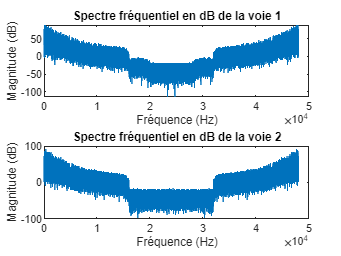


% Calcul de la corrélation inter-canal
correlation = corr(audio(1,:)', audio(2,:)');

% Spectre fréquentiel en dB de la séquence audio
figure;
subplot(2,1,1);
plot(f, TF_audio_dB(1,:));
xlabel('Fréquence (Hz)');
ylabel('Magnitude (dB)');
title('Spectre fréquentiel en dB de la voie 1');

subplot(2,1,2);
plot(f, TF_audio_dB(2,:));
xlabel('Fréquence (Hz)');
ylabel('Magnitude (dB)');
title('Spectre fréquentiel en dB de la voie 2');


% Calcul de l'énergie par bande de fréquences
numBands = 10; % Nombre de bandes de fréquences
bandEnergy = zeros(2, numBands);
for i = 1:numBands
    lowerFreq = (i - 1) * (fe / (2 * numBands));
    upperFreq = i * (fe / (2 * numBands));
    bandIndices = find(f >= lowerFreq & f <= upperFreq);
    bandEnergy(1, i) = sum(TF_audio(1, bandIndices).^2);
    bandEnergy(2, i) = sum(TF_audio(2, bandIndices).^2);
end

% Transposer la matrice TF_audio_dB pour que les dimensions correspondent
TF_audio_dB = TF_audio_dB';

% Sous-échantillonnage des vecteurs t et f
subsample_factor = 10; % Facteur de sous-échantillonnage
t_subsampled = t(1:subsample_factor:end);
f_subsampled = f(1:subsample_factor:end);

% Création de la grille de coordonnées à partir des vecteurs sous-échantillonnés
[T, F] = meshgrid(t_subsampled, f_subsampled);

Error using repmat
Requested 1102296x1102296 (9052.9GB) array exceeds maximum array size preference (15.4GB). This might cause MATLAB to
become unresponsive.

Error in meshgrid (line 61)
        xx = repmat(xrow,size(ycol));

Related documentation



% Représentation du spectre en 3D
figure;
surf(T, F, TF_audio_dB);
xlabel('Temps (s)');
ylabel('Fréquence (Hz)');
zlabel('Magnitude (dB)');
title('Spectre 3D de l''audio');

% Spectrogramme
figure;
spectrogram(audio(1,:), hamming(512), 256, 512, fe, 'yaxis');
title('Spectrogramme de la voie 1');

% Analyse de la dynamique temporelle
dynamicRange = std(audio(1,:));

% Détection des événements sonores
soundEvents = detectSoundEvents(audio(1,:), fe);

% Comparaison avec un signal de référence (par exemple, une sinusoidale de référence)
refSignal = sin(2*pi*1000*t);
comparisonResult = compareWithReference(audio(1,:), refSignal);

% Visualisation des pics fréquentiels
[peaks, peakFreqs] = findpeaks(TF_audio(1,:), 'MinPeakHeight', 10);

% Affichage des informations
fprintf('Corrélation inter-canal : %.2f\n', correlation);
fprintf('Bande d''énergie pour la voie 1 : %s\n', mat2str(bandEnergy(1,:)));
fprintf('Bande d''énergie pour la voie 2 : %s\n', mat2str(bandEnergy(2,:)));
fprintf('Plage dynamique de la voie 1 : %.2f\n', dynamicRange);
disp('Evénements sonores détectés :');
disp(soundEvents);
disp('Résultat de la comparaison avec le signal de référence :');
disp(comparisonResult);
disp('Pics fréquentiels détectés :');
disp(peakFreqs);